# Análise do modelo SIR

clear all;
close all;
clc;


## Lendo os dados da Itália

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 03-Jun-2020 17:10:11

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "date1", "deaths", "confirmed", "active", "recovered", "new_confirmed", "new_recovered", "new_deaths"];
opts.VariableTypes = ["double", "datetime", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "date1", "InputFormat", "yyyy-MM-dd");

% Import the data
tbl = readtable("/Users/a1/Downloads/dados-italia.csv", opts);

## Convert to output type

VarName1 = tbl.VarName1;
date1 = tbl.date1;
deaths = tbl.deaths;
confirmed = tbl.confirmed;
active = tbl.active;
recovered = tbl.recovered;
new_confirmed = tbl.new_confirmed;
new_recovered = tbl.new_recovered;
new_deaths = tbl.new_deaths;

## Clear temporary variables

clear opts tbl


## Italia

Id = active;
Rd = recovered + deaths;
tempo = [0:1:max(length(Id))-1];

## Definindo o modelo não linear


% Definido em um bloco Simulink - SIR

N =  60e6;
Rinf = 180e3;
beta_r = - inv(Rinf)*log((N-Rinf)/N);
r = 2.2e-2;
beta = r*beta_r*1.005

beta = 3.6905e-10

S0 = N;
I0 = 2;
R0 = 0;

beta = (3e-3)*67;
r=2.2e-2;

options = simset('solver','ode45','MaxStep',0.01,'InitialStep',0.01,'ReturnWorkspaceOutputs', 'on');
y = sim('SIRmodel',200,options);


## Variáveis

I = y.logsout{1}.Values.Data; % Saída I
R = y.logsout{2}.Values.Data; % Saída R
S = y.logsout{3}.Values.Data; % Saída S
t = y.tout;


## Visualiação de simulação do modelo

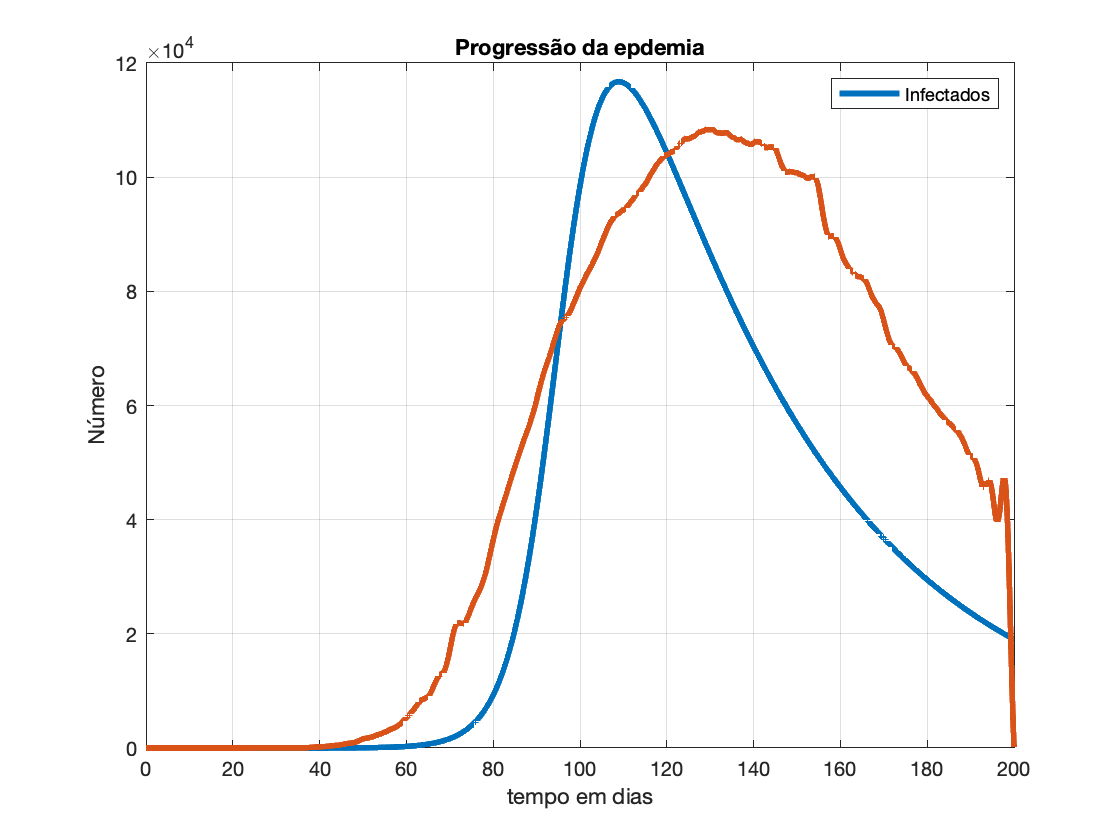

Id = resample(Id,length(I),length(Id));
Rd = resample(Rd,length(R),length(Rd));

figure()
plot(t,I*3e-3,t,Id,'Linewidth',3);
grid;
legend('Infectados');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

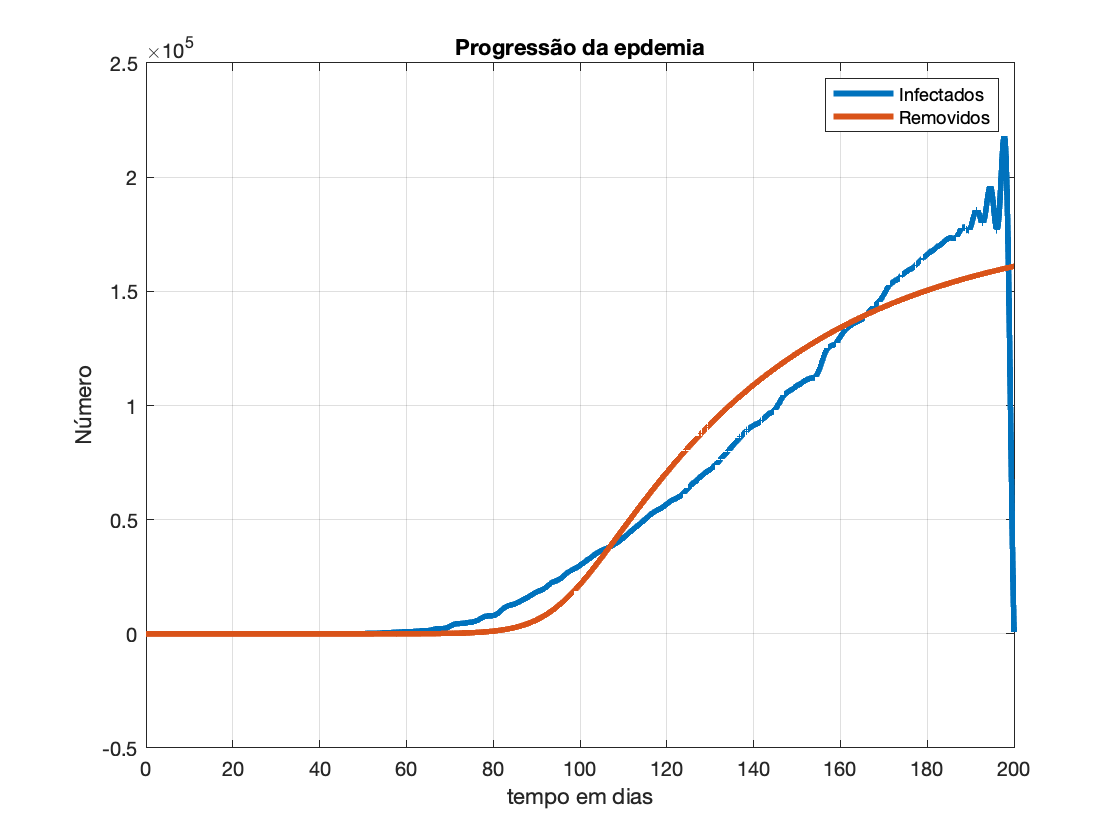


figure()
plot(t,Rd,t,R*3e-3,'Linewidth',3);
grid;
legend('Infectados','Removidos');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

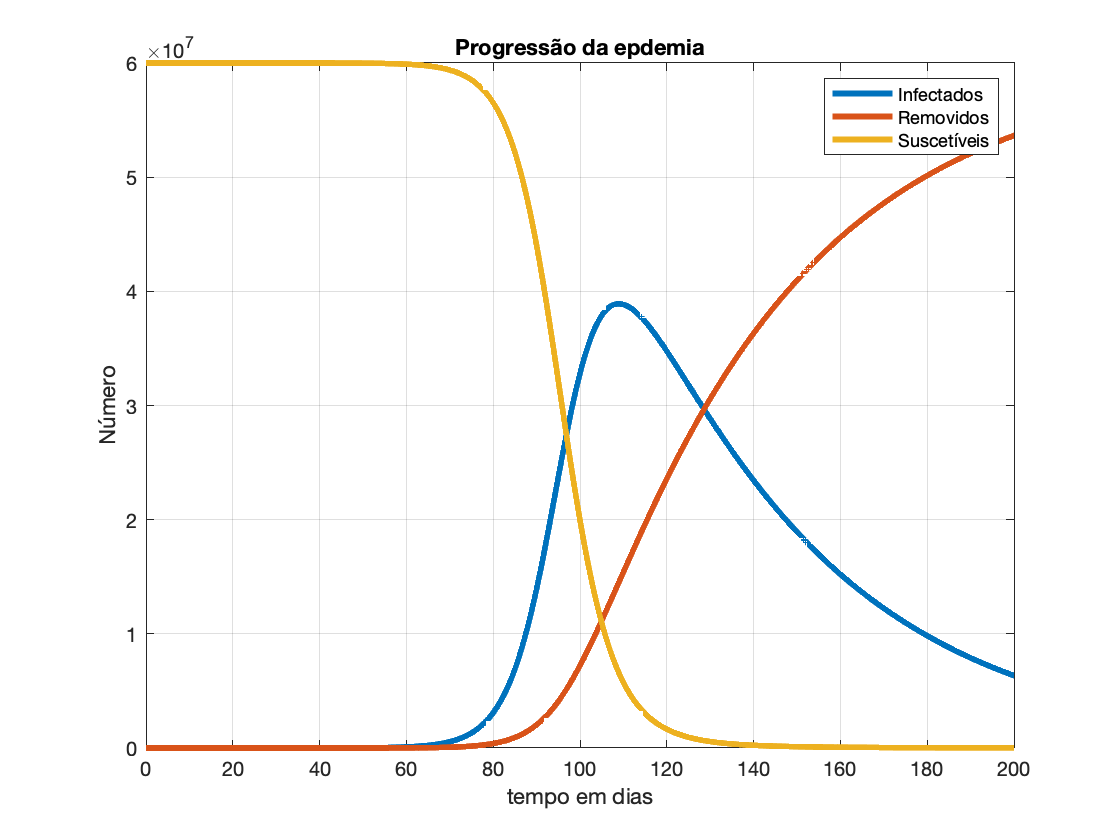



figure()
plot(t,I,t,R,t,S,'Linewidth',3);
grid;
legend('Infectados','Removidos','Suscetíveis');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

## Teste


sinf = (N-Rinf)/N
log(sinf)/(sinf-1)


## Análise de Ro


Ip_N = @(R0) 1 - (R0.^(-1).*(1+log(R0)))

R0 = [0.9:0.01:1.1];

plot(R0,Ip_N(R0));
xlabel('R0');
ylabel('Ip/N');
grid;
Ip = 110000/60e6
yline(Ip)
Rinf = 180e3;
N = 60e6;
(N-Rinf)/N
(1 - 0.9970)*N
R0 = log((N-Rinf)/N)/(-Rinf/N)

## Lendo os dados da Itália

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 03-Jun-2020 17:10:11

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "date1", "deaths", "confirmed", "active", "recovered", "new_confirmed", "new_recovered", "new_deaths"];
opts.VariableTypes = ["double", "datetime", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "date1", "InputFormat", "yyyy-MM-dd");

% Import the data
tbl = readtable("/Users/a1/Downloads/dados-italia.csv", opts);

## Convert to output type

VarName1 = tbl.VarName1;
date1 = tbl.date1;
deaths = tbl.deaths;
confirmed = tbl.confirmed;
active = tbl.active;
recovered = tbl.recovered;
new_confirmed = tbl.new_confirmed;
new_recovered = tbl.new_recovered;
new_deaths = tbl.new_deaths;

## Clear temporary variables

clear opts tbl


## Visualizando os gráfico

Id = active;
Rd = recovered + deaths;
tempo = [0:1:max(length(Id))-1];


figure()
plot(tempo,Id,tempo,Rd,'Linewidth',3);
grid;
legend('Infectados','Removidos');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

## Ajustando os parâmetros do modelo

x0 = [2.2e-2*1.0015 2.2e-2]
options = optimset(options,'Display','iter','TolFun',1e-12,'Tolx', 1e-12);

[X,FVAL,EXITFLAG] = fminsearch(@(x) ErroQuadraticoSIR(x,Id,Rd) ,x0, options) 


